# Frequency Sampling Design of FIR Filters

This live script is based on the discussion in MATLAB Exercise 8.17 of 

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

Using the frequency sampling design method, design a length-$25$ linear-phase multiband filter to approximate the ideal magnitude response given below.


$$  \left|H_{d}\left(\Omega\right)\right| =
  \left\{
  \begin{array}{l l}
    1\;,\quad   &  0<\left|\Omega\right|<0.2\pi       \\[4pt]
    0.5\;,\quad &  0.3\pi<\left|\Omega\right|<0.55\pi \\[4pt]
    0\;,\quad   &  0.65\pi<\left|\Omega\right|<\pi
  \end{array}
  \right.$$


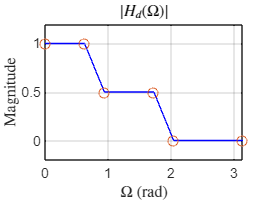

% Graph the filter specifications
Omg = [0,0.2,0.3,0.55,0.65,1]*pi;
Hd = [1,1,0.5,0.5,0,0];
plot(Omg,Hd,'b-',Omg,Hd,'o'); grid;
axis([0,pi,-0.2,1.2]);
set(0,'defaultTextInterpreter','latex');
title('$|H_{d}(\Omega)|$');
xlabel('$\Omega$ (rad)');
ylabel('Magnitude');

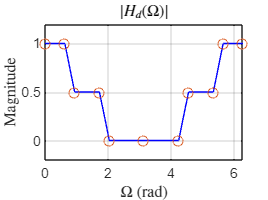

% Mirror the specifications to fill 0 to 2*pi
Omg = [Omg,2*pi-Omg(end-1:-1:1)];
Hd = [Hd,Hd(end-1:-1:1)];
plot(Omg,Hd,'b-',Omg,Hd,'o'); grid;
axis([0,2*pi,-0.2,1.2]);
title('$|H_{d}(\Omega)|$');
xlabel('$\Omega$ (rad)');
ylabel('Magnitude');

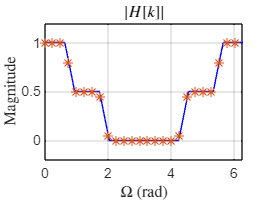

% Frequency sampling to obtain |H[k]|
N = 25;
M = (N-1)/2;
k = [0:N-1];
Omgk = 2*pi*k/N;
Hk = interp1(Omg,Hd,Omgk);
plot(Omg,Hd,'b-',Omgk,Hk,'*'); grid;
axis([0,2*pi,-0.2,1.2]);
title('$|H[k]|$');
xlabel('$\Omega$ (rad)');
ylabel('Magnitude');

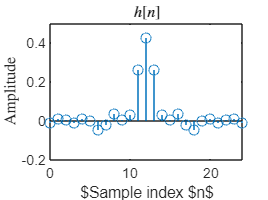

% Inverse DFT to obtain h[n]
h = real(ifft(Hk.*exp(-j*Omgk*M)));
n = [0:N-1];
stem(n,h);
axis([0,24,-0.2,0.5]);
title('$h[n]$');
xlabel('$Sample index $n$');
ylabel('Amplitude');

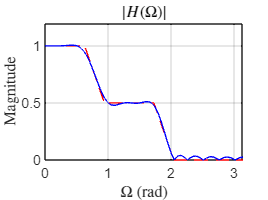

Omega = [0:0.002:1]*pi;
H = freqz(h,1,Omega);  % Compute frequency response
plot(Omg,Hd,'r--',Omega,abs(H),'b-'); grid;
axis([0,pi,0,1.2]);
title('$|H(\Omega)|$');
xlabel('$\Omega$ (rad)');
ylabel('Magnitude');

set(0,'defaultTextInterpreter','tex');